# MXB161 IW5 Sound Processing 1

This is your Individual Worksheet (IW).  Complete this worksheet at your own pace.  After you've completed the worksheet, you'll be ready to take the Quiz for this topic.

**This week the Quiz is part of this same worksheet.  You'll find it at the end of this document.**

## Getting started

This worksheet is designed to be completed in conjunction with the associated online lecture on Canvas.

If you haven't yet started the online lecture, please start that first.  You'll be directed to return to this worksheet at the appropriate time in the lecture.

## 5.1 Make your own note

We'll start by making a "pure" musical note. A note of frequency **f**, measured in cycles per second or Hertz (Hz), is described by the function 


$$y = \sin(2 \pi f t)$$


The standard frequencies of notes can be found online. For example, the note of high C has frequency $f = 523.251$ Hz. To create this sound in MATLAB, we need to decide two things: the duration of the sound, and the *sampling rate*. Let's choose a duration of 1 second. Now, let's *sample* the sine function above at 8192 equally spaced points between 0 and 1. In other words, our sampling rate is 8192 *samples per second*.

f = 523.251;       % the frequency of our note
Fs = 8192;         % the sampling rate
t = 0:1/Fs:1;      % an array of t values equally spaced from 0 to 1
y = sin(2*pi*f*t); % the sine wave sampled at these values of t
sound(y,Fs)        % now play the sound

You should hear a pure tone when you play this sound.

You can also plot the waveform that has been sampled.  There are 8193 samples in total, but we'll just plot the first 128 to get the idea.

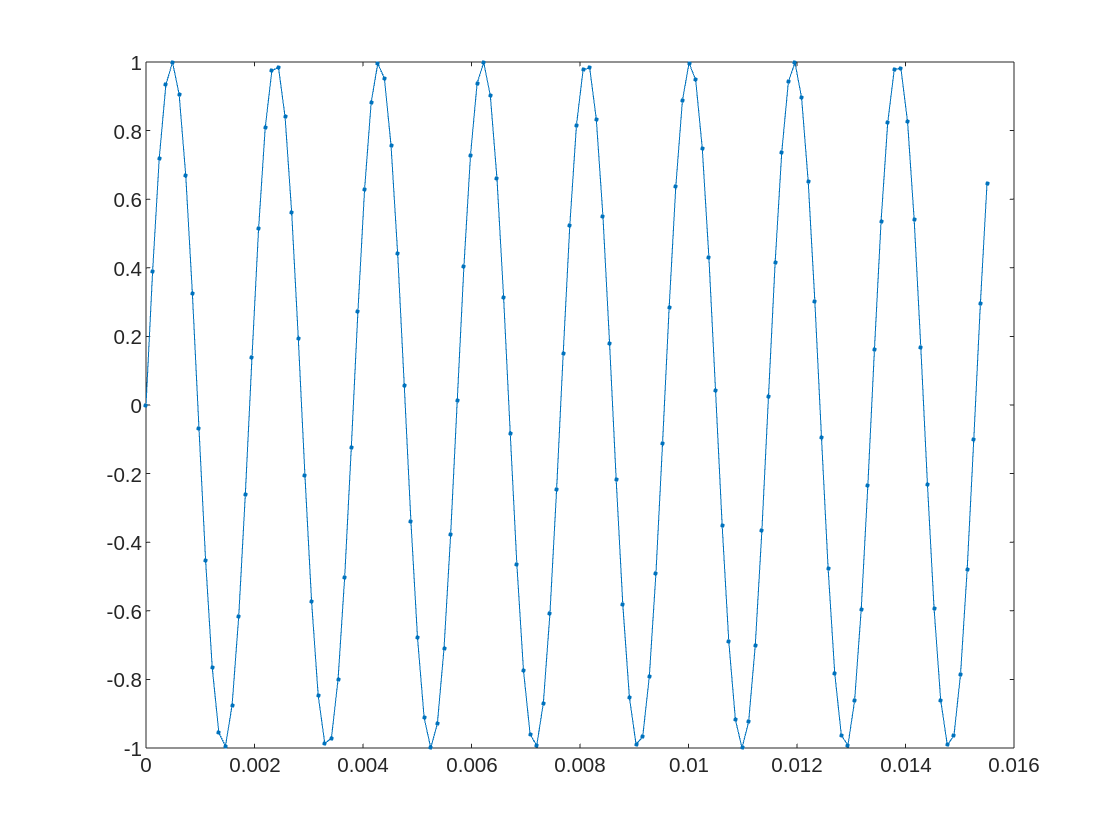

figure
plot(t(1:128), y(1:128), '.-')
hold on

You can see that the wave is not perfectly represented by our discrete samples (it's a bit sharp around the peaks).  But we have enough samples that it still sounds "smooth" to our ears (though, if you have very good hearing and/or a good set of headphones, you may be able to hear that it's not entirely smooth).

### Sampling rate

If we reduce the sampling rate too far, we will be able to hear the difference. Redo the example, with a sampling rate of **Fs2** = 2048. Call the new arrays **t2** and **y2**.

f = 523.251;       % the frequency of our note
Fs2 = 2048;         % the sampling rate
t2 = 0:1/Fs2:1;      % an array of t values equally spaced from 0 to 1
y2 = sin(2*pi*f*t2); % the sine wave sampled at these values of t
sound(y2,Fs2)        % now play the sound

Through a decent set of headphones you will hear the difference between **y** and **y2**.  Certainly we can see the difference by plotting.  **hold** your earlier figure, and plot **y2(1:32)** against **t2(1:32)** on the same axes.

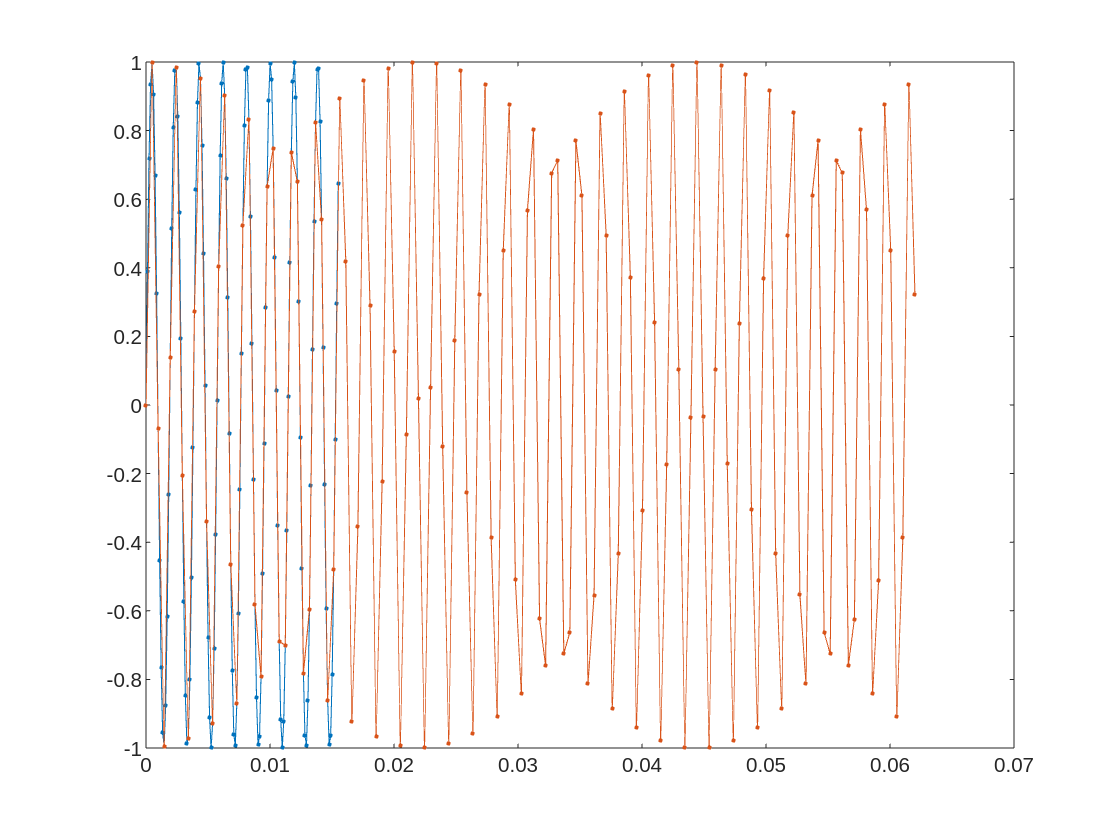

plot(t2(1:128), y2(1:128), '.-')

You can add a legend using the comment

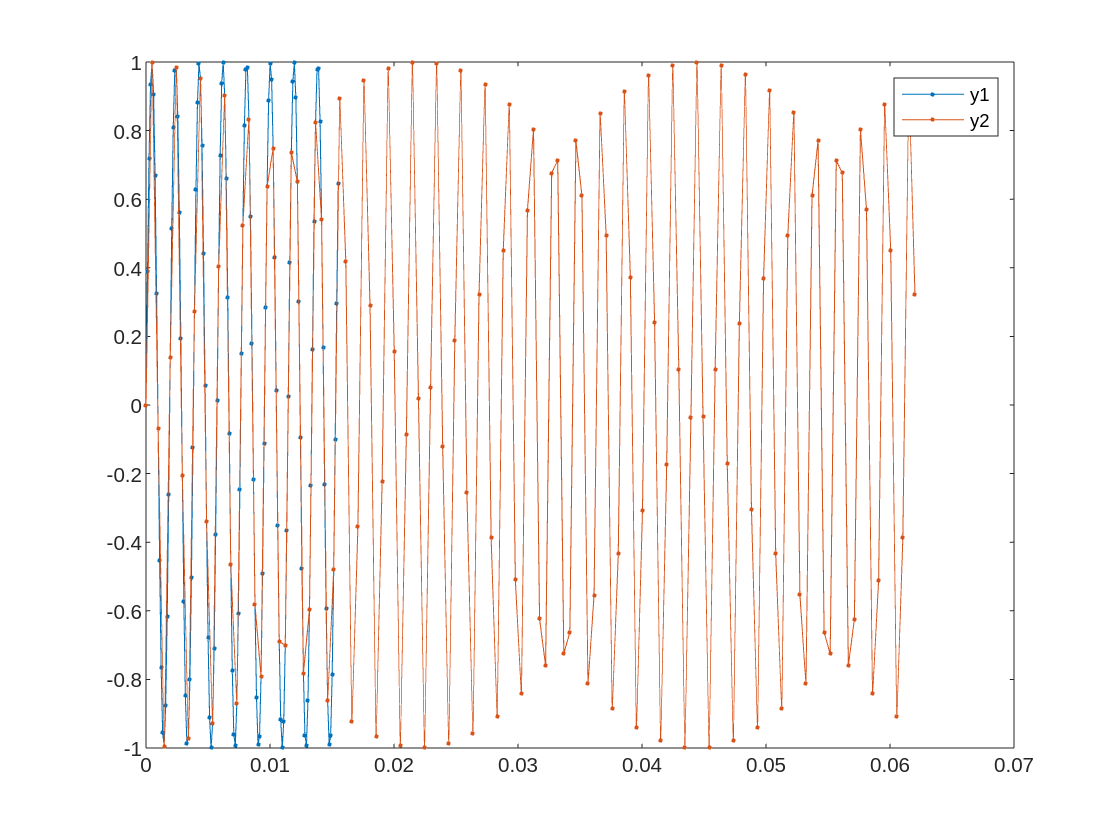

legend('y1', 'y2')

You should get a figure like this:

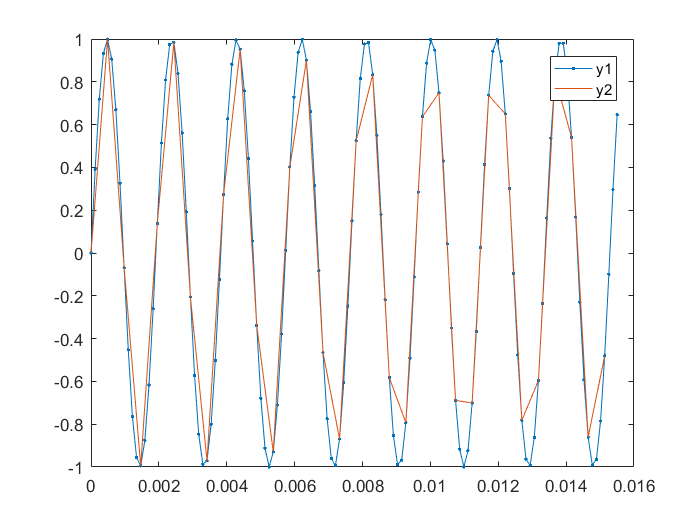

The array **y2** really doesn't sample the waveform enough to capture its true character.

### Volume

The volume of the sound is determined primarily by your operating system and/or speaker's volume settings. However, we can *reduce* the volume by reducing the amplitude of the wave. Create a new array **y3** which is the sine wave with *half* the amplitude of **y**.

f = 523.251;       % the frequency of our note
Fs2 = 2048;         % the sampling rate
t2 = 0:1/Fs2:1;      % an array of t values equally spaced from 0 to 1
y3 = sin(2*pi*f*t2)/2; % the sine wave sampled at these values of t
sound(y2,Fs2)        % now play the sound

Compare the relative volumes when you play **y3** compared to **y**.  Also produce the figure shown below.

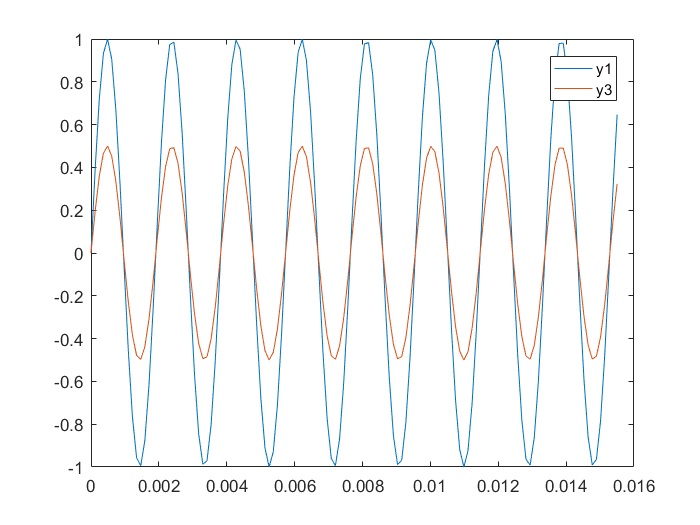

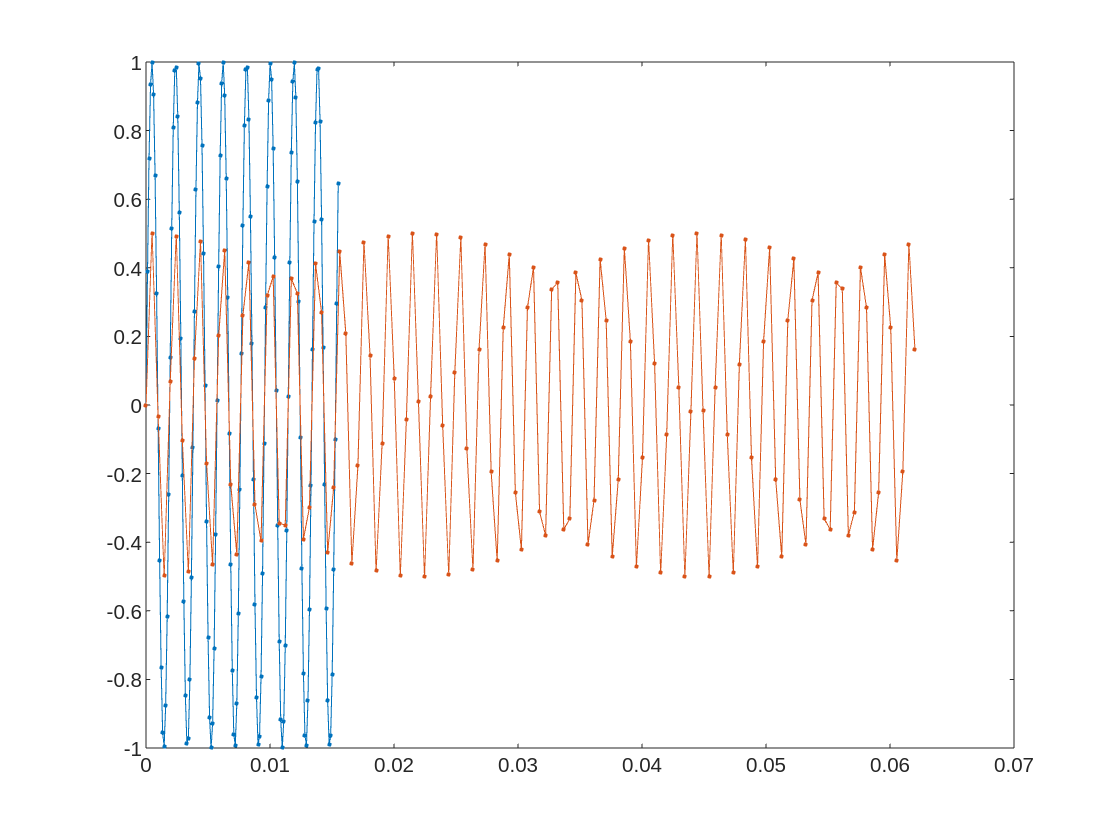

plot(t2(1:128), y3(1:128), '.-')

MATLAB also provides a command **soundsc** (sc for "scaled") that automatically scales the array to the limits [-1, 1] before playing.  This essentially means the sound plays at full volume, subject to your operating system and/or speaker's volume settings.  Confirm that **y** and **y3** sound the same, when played using **soundsc**.

soundsc(y3,Fs2) % YES

### Frequency

Redo the first example (**y**) with the frequency **f** = 261.626 Hz. Call this array **y_half_f**. Does the note sound higher or lower compared to **f** = 523.251?

%f = 523.251;
y_half_f = 261.626;       % the frequency of our note
Fs = 8192;         % the sampling rate
t = 0:1/Fs:1;      % an array of t values equally spaced from 0 to 1
y = sin(2*pi*y_half_f*t); % the sine wave sampled at these values of t
sound(y,Fs)        % now play the sound

% LOWER

Redo the first example (**y**) with the frequency **f** = 1046.50 Hz.  Call this array **y_double_f**.  Does the note sound higher or lower compared to **f** = 523.251?

%f = 523.251;
y_double_f = 1046.50;       % the frequency of our note
Fs = 8192;         % the sampling rate
t = 0:1/Fs:1;      % an array of t values equally spaced from 0 to 1
y = sin(2*pi*y_double_f*t); % the sine wave sampled at these values of t
sound(y,Fs)        % now play the sound

% LOWER

### Specifying incorrect sampling rate

Suppose we play back the sound **y**, but specify an incorrect sampling rate **Fs**. For example:

sound(y, Fs*2)

What do you hear?  Which of **y_half_f** or **y_double_f** does it sound like?  Notice that it only plays for *half* as long, since it's playing back *twice* as many samples per second.

% Sounds Like y_double_f (higher)

Repeat for

sound(y, Fs/2)

Describe what you hear this time.

% Sounds Like y_half_f  (lower) half song

**Well done on finishing this section**.  Now you can return to the online lecture.

## 5.2 Manipulating sounds

MATLAB comes with some built-in sound recordings saved as MAT (workspace) files.  To find out what variables are in a MAT file, you can use the **who **command on the file.

who -file gong


Your variables are:

Fs  y   



You can see that the **gong** file contains variables called **Fs** and **y**.  When you load a MAT file, you will *overwrite* any variables in your existing workspace that have the same name as those in the MAT file. So if you don't want to lose your own **y** and **Fs**, give them other names now, before executing the next command.  (Or, you could save your own workspace to a file first: **save myworkspace**.)

load gong
sound(y, Fs)

It sounds like a gong. You can also plot the waveform represented by the array **y**.

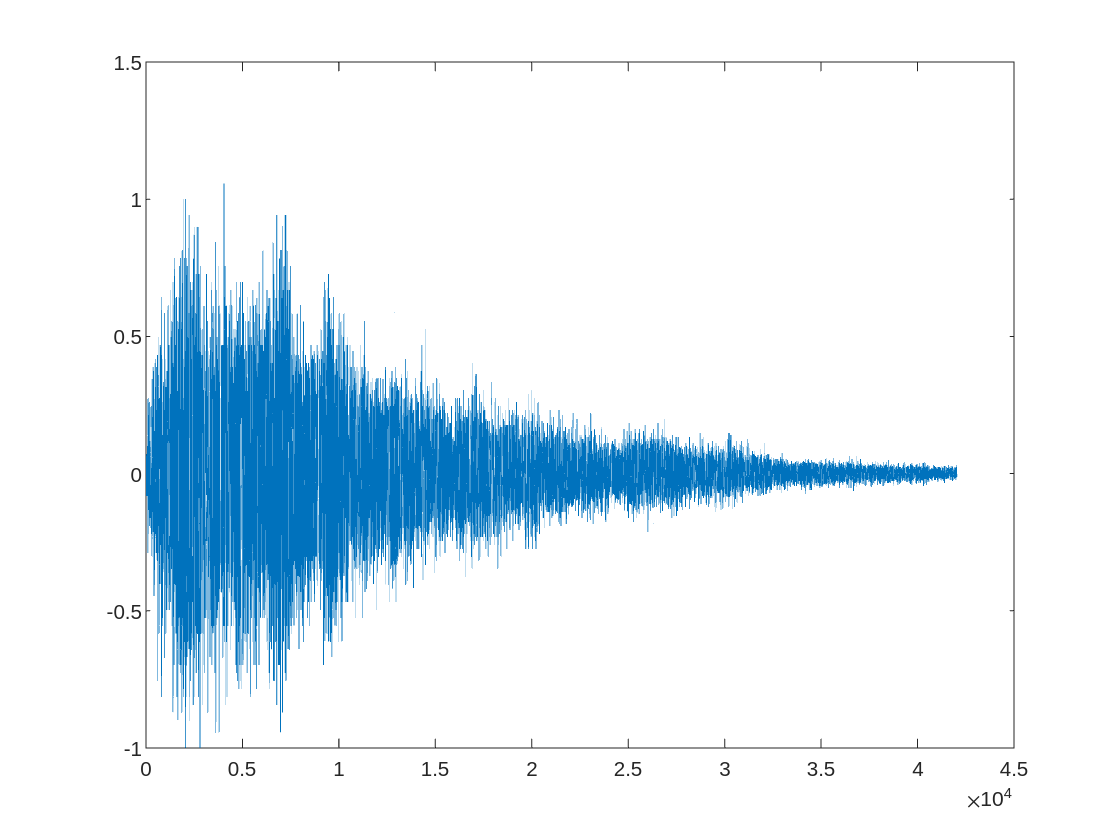

plot(y)

You can see the waveform is much more complex than for the simple tone we created.  Notice that here, we said **plot(y)** rather than **plot(t, y)**.  So the horizontal axis is not time, but rather the index into the **y** array.  Hence, the horizontal axis goes from 1 up to **length(y)**.

What sound do the following commands produce?  Try to figure it out first, then play it to confirm you're correct.

Y = [y; y];
sound(Y, Fs)
% Two gongs one after anouther

What sound do the following commands produce?  Try to figure it out first, then play it to confirm you're correct.

y2 = y(1:2000); 
Y = [y2; y2; y2; y2; y];
sound(Y, Fs)

Load the built-in **handel** sound recording, also called **y**.  Play it once.

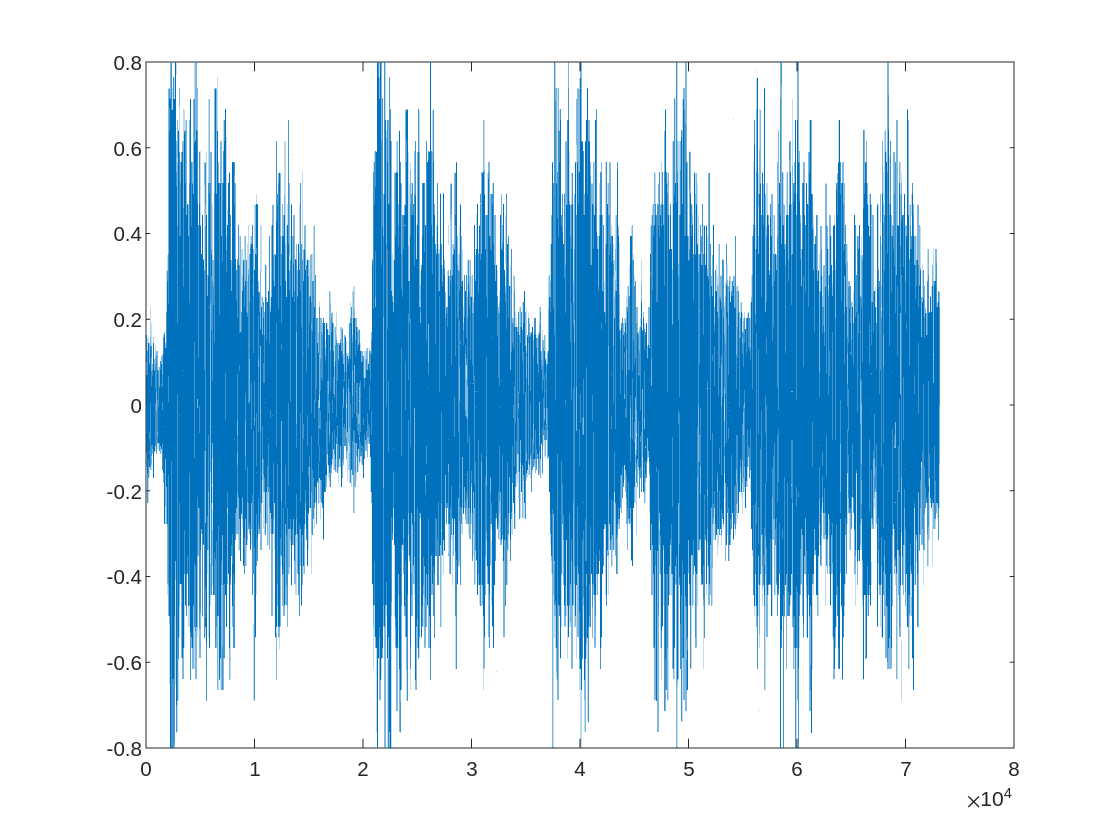

figure
load handel; y_handel = y;
sound(y_handel, Fs)
plot(y_handel)

Plot the waveform for this sound, and use your eyes to estimate where the first "Hallelujah" starts and ends.  Use the **Data Cursor** to identify the indices into the array (the horizontal coordinates) that enclose this section of the sound.  What are these indices?

figure
plot(y_handel)

% Around 1000 to 17000

From what you just found, what command will play just the first "Hallelujah"?  Try it to confirm.

y_handel_2 = y_handel(1000:17000);
sound(y_handel_2)

Now we want to **load** some other built-in sounds, all of which are called **y**.  First we'll make a copy of our existing **y** with a unique name.

y_handel = y;

Now we can **load** (and copy) the other built-in sound recordings: **laughter**, **train**, **chirp** and **splat**.

load laughter; y_laughter = y;
load train; y_train = y;
load chirp; y_chirp = y;
load splat; y_splat = y;

The sampling rates are all the same. Play these four sounds now.

sound(y_laughter, Fs)
sound(y_train, Fs)
sound(y_chirp, Fs)
sound(y_splat, Fs)

Write a command to play **laughter** at double speed. Chipmunks!

sound(y_laughter, Fs*2)

Write a command to play **splat** at half speed.

sound(y_splat, Fs/2)

Write a command to give 4 toots of the **train** whistle.

sound([y_train; y_train], Fs)

Write a *single command* to play **chirp** followed by **splat** and then **laughter** (oh how cruel!)

sound([y_chirp; y_splat; y_laughter], Fs)

We can also combine sounds to play *together*. For example, let's add a laughter track to Handel's "Hallelujah".  First, we must make the two arrays the *same length*.  Since the **laughter** array is the shorter of the two, we'll just duplicate some of that array to lengthen it. The code below assumes you have loaded both sounds, and named them accordingly:

length_handel   = length(y_handel);
length_laughter = length(y_laughter);
delta           = length_handel - length_laughter;
y_laughter2     = [y_laughter; y_laughter(1:delta)];

You can confirm now in your Workspace Window that **y_handel** and **y_laughter2** are the same length.  Now we just need to combine the waveforms.

y_funny_handel = y_handel + y_laughter2;

To play back this combined waveform, we should use **soundsc**, to ensure the scaling is mapped back to [-1, 1].

soundsc(y_funny_handel, Fs)

**Well done on finishing this section**.  Now you can return to the online lecture.

## 5.3 A simple electronic keyboard

Load the file **piano,** which contains an array **C** and sampling rate **Fs**.

load piano.mat
sound(C, Fs)

Plot the array **C**, which is the waveform of a piano playing the node middle C, frequency 261.626 Hz.

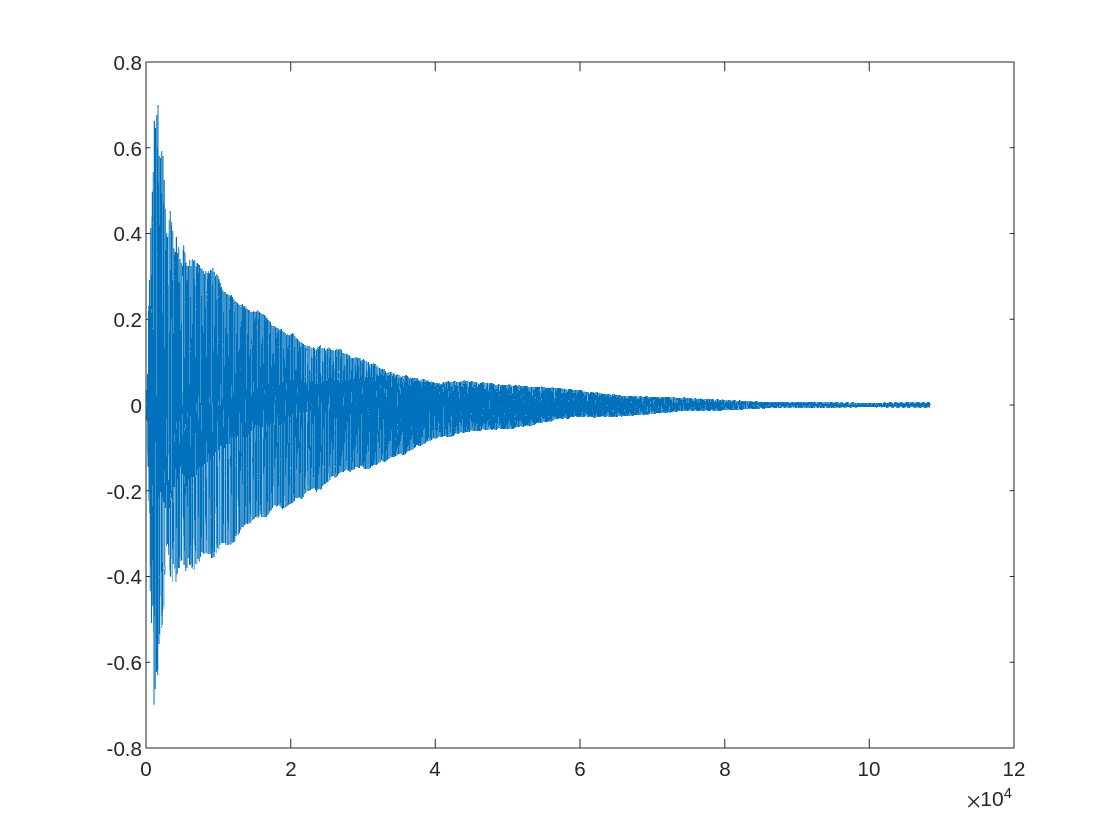

plot(C)

What is the sampling rate for this recording?  It's much higher than we've been using so far.

piano = audioplayer(C, Fs)

piano =   audioplayer with properties:

       SampleRate: 44100
    BitsPerSample: 16
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 108396
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audioplayer'


% Sample Rate 8192

Play the sound now.

play(piano)

Suppose we'd like to use this recording to simulate a simple electronic keyboard. A low-tech solution is simply to play back this same recording using *different* sampling rates, to simulate different notes. For example

sound(C, 2*Fs)

is the sound of *high* **C**, one octave above middle **C**. Naturally, by doubling the playback sampling rate, the sound only plays for half as long.  That's why we called this a low-tech solution!  But still, it will be enough for our purposes today.

Other notes between these two can be simulated by playing back the same sound at sampling rates between **Fs** and 2***Fs**.  The notes of **E** and **G** can be played using sampling rates of 5/4***Fs** and 3/2***Fs** respectively:

sound(C, 5/4*Fs)  % E

sound(C, 3/2*Fs)  % G

Altogether, so far we have

sound(C, Fs), pause(1), sound(C, 5/4*Fs), pause(1), sound(C, 3/2*Fs), pause(1), sound(C, Fs*2)

This sequence is part of the **C** Major scale.  The rest of the scale (which in its entirety is **C D E F G A B C**) can be completed by consulting the following table.

`Note - Sampling Rate`

`C - Fs`

`D - 9/8*Fs`

`E - 5/4*Fs`

`F - 4/3*Fs`

`G - 3/2*Fs`

`A - 5/3*Fs`

`B - 15/8*Fs`

`C - 2*Fs`

Note that in this instance we can't easily combine the scale into a single array, something like

%this_wont_work = [C; D; E; F; G; A; B; C2]

since we don't have separate recordings for **D**, **E**, **F**, etc.  We only have one recording for **C**, which we use to "fake" the others by playing back at *different* sampling rates.  More advanced solutions would *resample* the **C** note, to create new sounds for **D**, **E**, **F**, etc.  But we won't do that.

**Well done on finishing this section**.  Now you can return to the online lecture.

# **Exercises**

**1. C Major scale in beeps and boops**

Write code to play the C Major scale by composing eight pure sine waves of the correct frequencies, and concatenating them into a single array.  The code should play the full scale with a single call to the **sound** function.

**1. C Major scale on a piano**

Write code to play the C Major scale by playing back the single piano note at different rates.  The code should play the eight notes in the correct order using 8 different calls to the **sound** function with adjusted sampling rates, and **pause**s in-between.

# **Quiz**

**There is no auto-marked MATLAB Grader Quiz this week.**

Instead, your Quiz for this week requires you to submit a MATLAB Live Script file **music.mlx**, and an audio file **music.wav**.  You submit these through the Quiz 5 link on Canvas.

## Composing music

Your task is to compose a short piece of electronic music.  The piece must conform to the following rules (and no amount of complaining that "music doesn't have rules, man" will change that):

1. It must be between 10 and 15 seconds long.

2. It must be sampled at the rate **Fs** = 8192.

3. It must incorporate at least three of the built-in sounds **handel**, **gong**, **laughter**, **train**, **chirp** and **splat**.  These can be incorporated in part, in full, or repeated several times (in part or in full).

4. It must include sounds playing at the same time as others.

5. It may include pure notes created using sine waves, but this is optional.

6. It may include **piano** notes, but this is harder than it might seem: they will need to be resampled to match the sampling rate of 8192.  You'll have to work this out yourself if you want to try.

7. No other sounds may be included in the piece.  So no sampling your own voice, no downloading other clips, etc.

8. The final piece must be represented by a *single* array **y**.

9. The code you submit must construct your piece from an empty workspace -- so **load** any samples you use.

Write your code to compose the music in a script file **music.mlx**.  The last commands of this file should save your creation as a wave file as follows:

Naturally you should listen to your final creation to ensure it's satisfactory.  When all is ready, submit both files:

- **music.mlx**

- **music.wav**

through the Quiz 5 link on Canvas.